# **SENT - Serial Messages SPC**

This example demonstrates how the SENT protocol communicates with one Tx node and one Rx node, which are both on the same I/O module. You can test the basic functionality of the SENT protocol by running this loopback test. 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports **1x SENT Tx channel** and **1x SENT Rx channel  **     

- Connector cable from the I/O module to the terminal board

- Terminal board with one jumper wire

### Test Setup

In this example, data is sent from the SENT Tx channel to the SENT Rx channel. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file (bitstream) used. 

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect theses pins with jumper wires. 

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_SENT_serialMessagesSPC';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

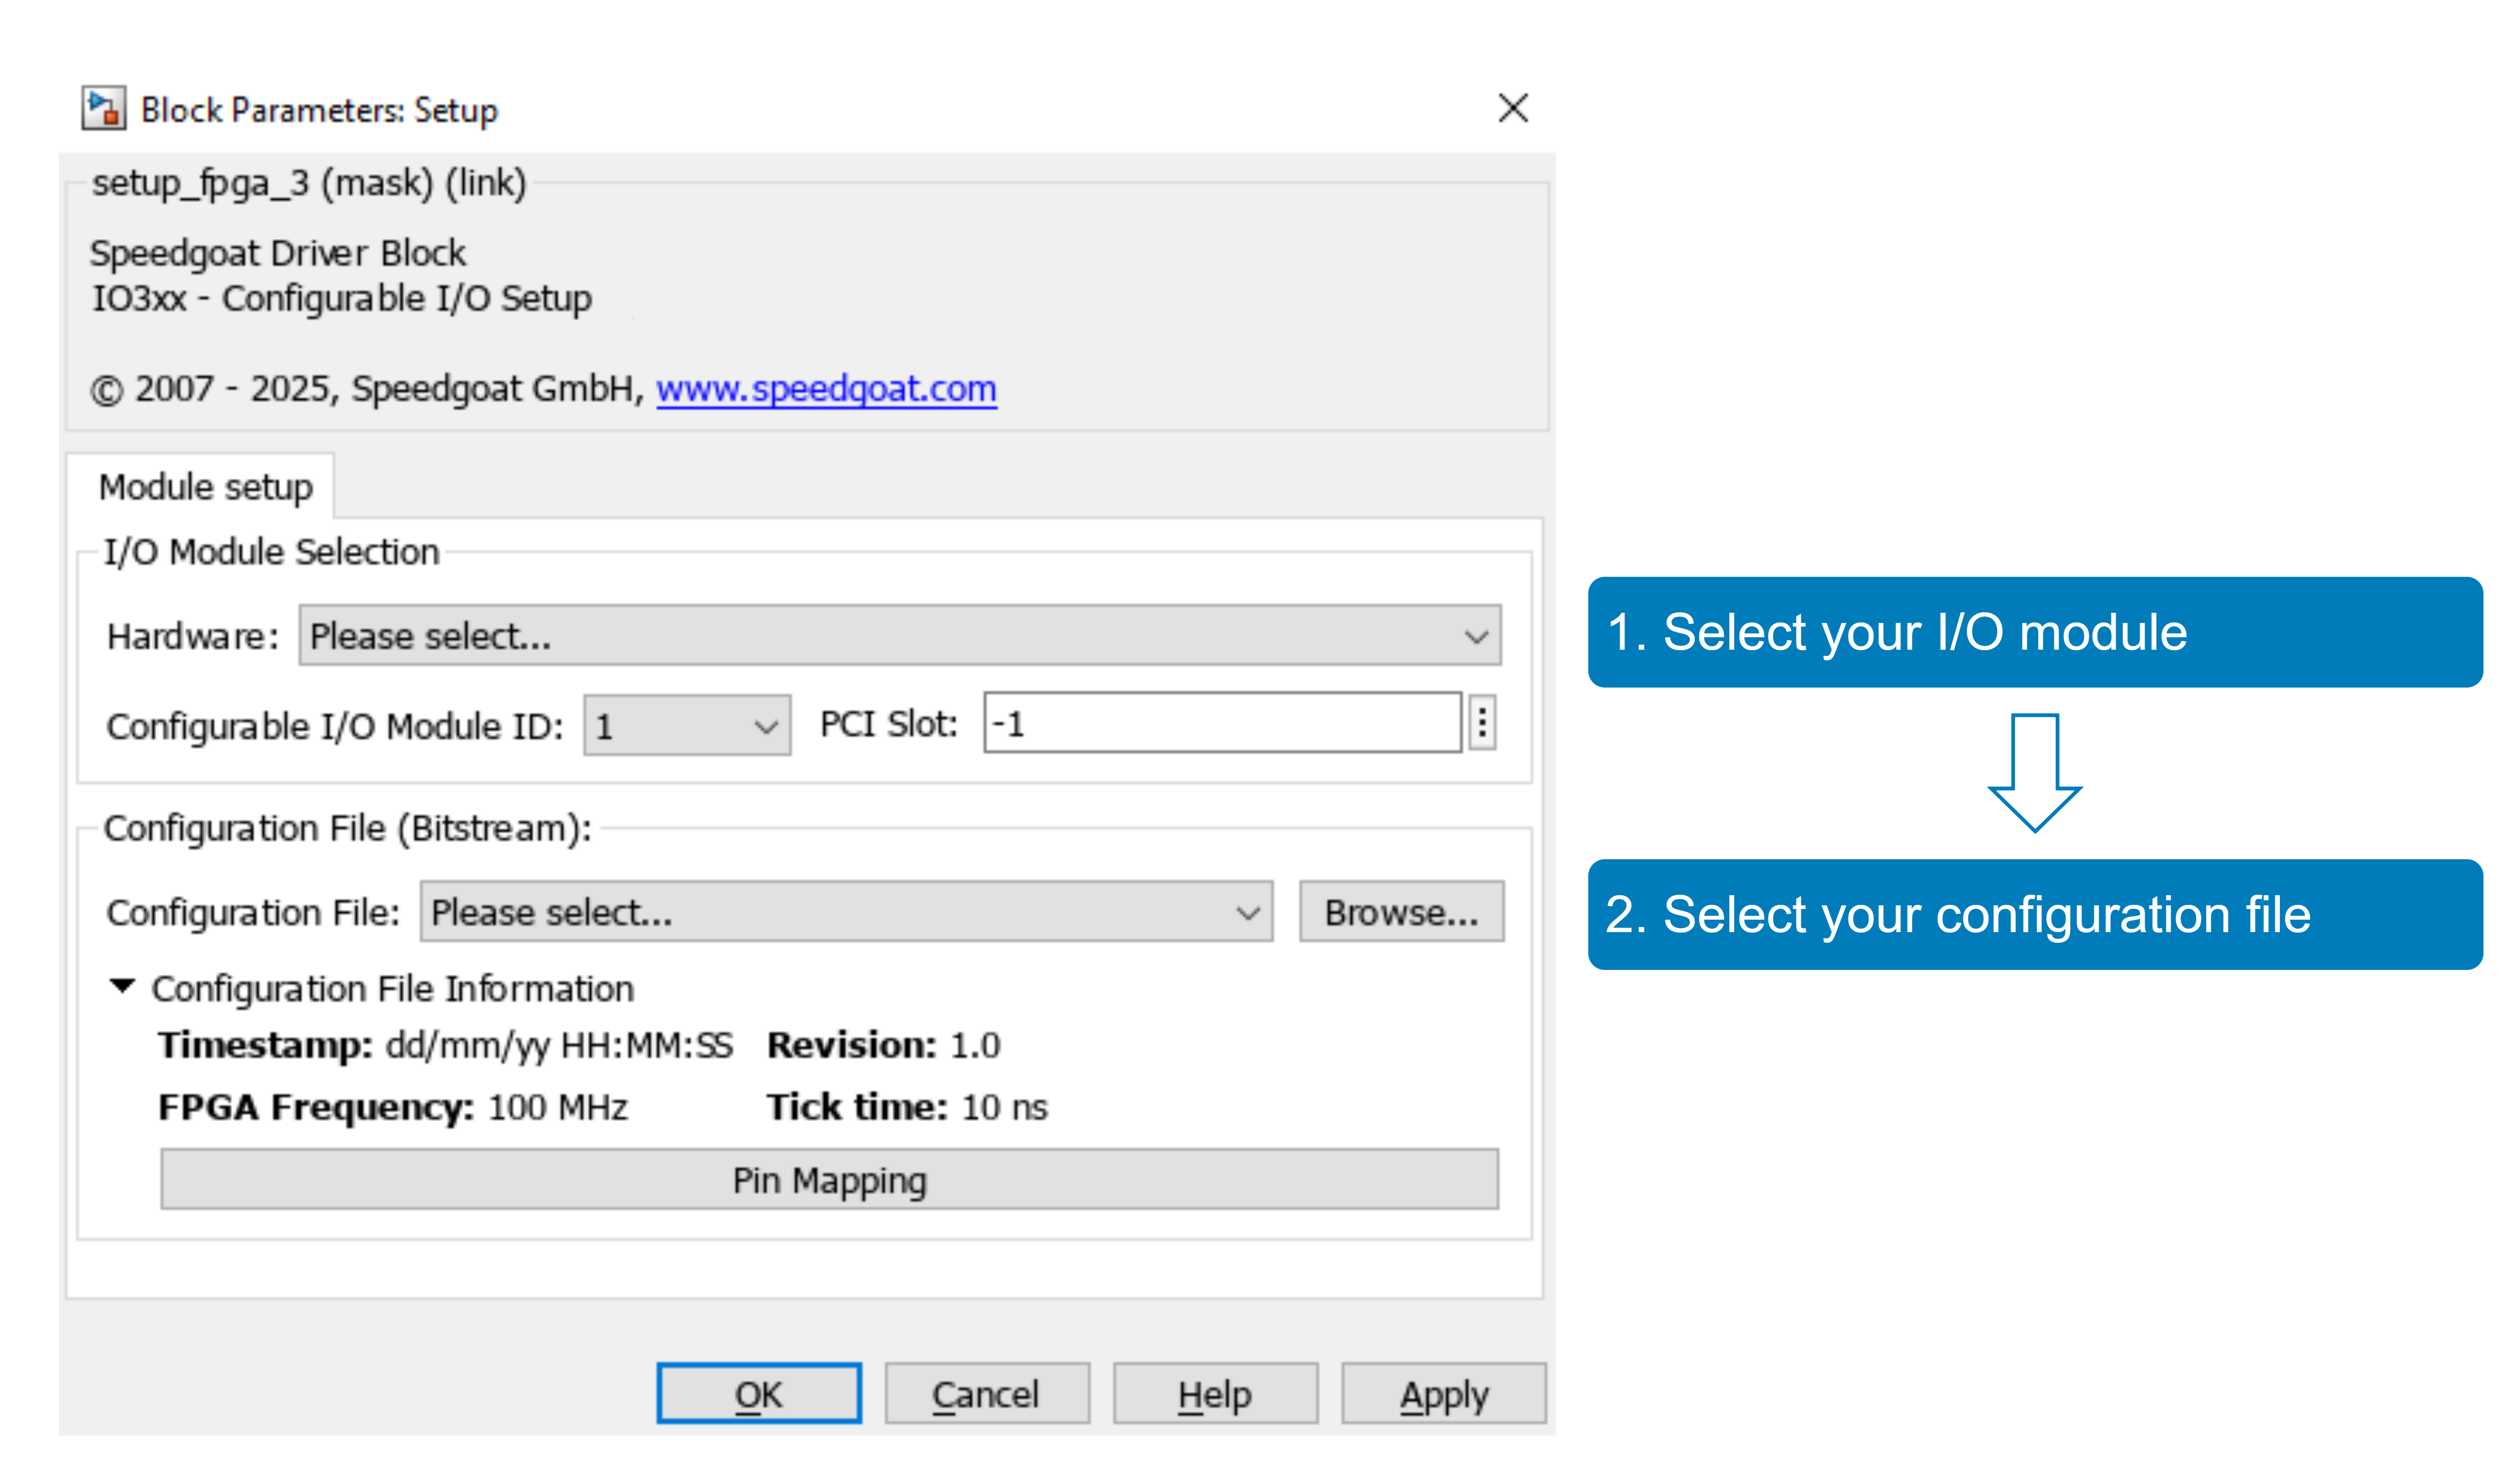

With the **Pin Mapping** button you can now check where the functionalities are located.

### Model Description

In the model a counter is connected to the SENT Tx block for one fast message.

The fast message status depends on the counter;

- Counter 0...499     --> Status = 0

- Counter 500...749 --> Status = 1

- Counter 750...999 --> Status = 3

In this example, the SENT protocol is setup to also transfer enhanced serial messages and the synchronization mode is set to SPC (short PWM control).

Note that the data format depends on the drop-down menu selection in the SENT tab of the SENT Tx block. For this model, the "Secure sensor with one 12-bit fast channel, fast message 1 and secure sensor information on fast message 2 (H4)" data format is used on the [SENT Transmit (Tx)](https://www.speedgoat.com/help/slrt/page/io_main/refentry_sent_tx_v1) block.

The fast message, the H4-secure channel (on fast message 2, bit-unpacking in the model), fast message status and enhanced serial message are received by the [SENT Receive (Rx)](https://www.speedgoat.com/help/slrt/page/io_main/refentry_sent_rx_v1) block and the signals are directly connected to a Simulink scope, where they can be inspected. Additionally, the fast message error status, fast message valid counter, fast message error counter and serial message error counter can be inspected by a display.

The SENT Transmitter and Receiver are running in **Synchronous Transmission SPC** mode which means that a single SENT frame is transmitted only when it is requrested by the SENT Receiver. This request is generated on the SENT Receiver once with every model step.

The SENT Transmitter's and Receiver's option **Enable Enhanced Serial Message** is set. Therefore the blocks contain also signals to generate and receive enhanced serial messages which are also known as slow messages. A single enhanced serial message is transferred during 18 fast messages. The [SENT Transmit (Tx)](https://www.speedgoat.com/help/slrt/page/io_main/refentry_sent_tx_v1) block indicates with it's output **serial msg buffered** that the serial message on the inputs **serial msg ID** and **serial msg data** are buffered and beeing transmit. This output is used to increment a counter so that the ID and data of the serial message are continuously increasing. The input **serial msg Config** is set to 0, the serial message ID therefore is 8bit and the serial messsage data is 12bit.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode',   'external')   % put model into External Mode
set_param(modelName, 'SimulationCommand','connect')    % connect with External Mode  

% Set Stop-Time to 8s and start the real-time application
tg.setStopTime(8);
tg.start;



### Check the Results

Open the **Fast Message** Simulink scope connected to the [SENT Rx](https://www.speedgoat.com/help/slrt/page/io_main/refentry_sent_rx_v1) block. On the Scope, following signals must be visible:

- **SENT_fast_msg1**

- increasing counter between 0 and 999

- **H4_Rolling_Counter**

- increasing counter between 0 and 255

- **H4_N3_Inverted**

- represents the inverted 4 MSbits of the fast_msg1 which is a 12bit counter value between [0...999]. The 4MSbits therefore are [0...3], the corresponding bit-inversion is [15...12].

- **SENT_status**

- described in the model behavior: fast_msg1 = 0...499 --> status = 0 / fast_msg1 = 500...749 --> status = 1 / fast_msg1 = 750...999 --> status = 3

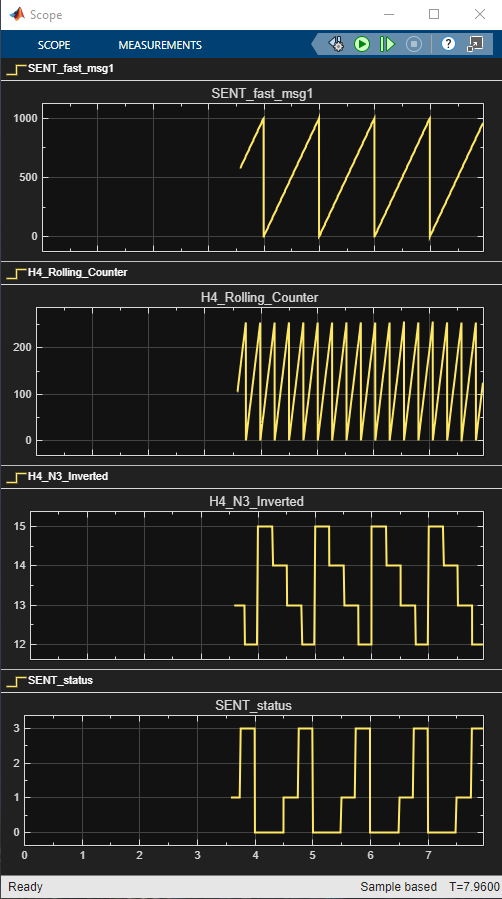

The displays showing "SENT_msg_errorStatus" and "SENT_msg_error_count" should be 0 (to indicate no error happened during data transmission).

Open the **Serial (Slow) Message** Simulink scope connected to the [SENT Rx](https://www.speedgoat.com/help/slrt/page/io_main/refentry_sent_rx_v1) block. On the Scope, following signals must be visible:

- **serial_msg_ID**

- increasing counter between 0 and 255 (the ID width is 8bit due to serial msg Config is set to 0)

- **serial_msg_Data**

- increasing counter between 0 and 1023 (the data width is 12bit due to serial msg Config is set to 0)

- NOTE: to see the full range, the simulation time must be enlarged

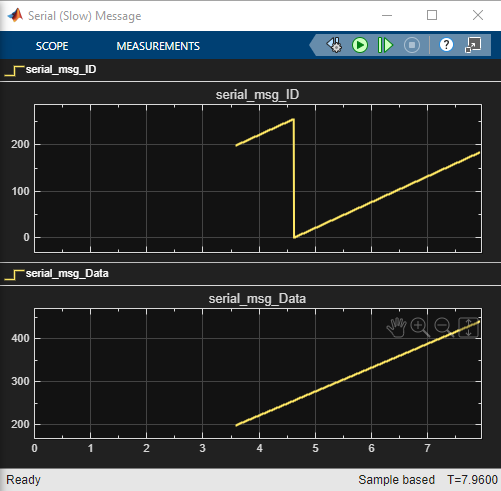

The displays showing "SENT_serial_msg_error_count" should be 0 (to indicate no error happened during data transmission).

## Additional References

- [SENT documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_sent)